# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data. You can assume the data has been properly prepared:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "Malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "Malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier, taking "Malignant" as the positive class, and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
%predicting labels for NaiveBayes and DecisionTree
[predictions_nb,score_nb] = predict(m_nb, test_examples);
[predictions_dt,score_dt] = predict(m_dt,test_examples);
%calculating likelihood and generating confusion matrix
[c_nb,order_nb]=confusionmat(test_labels,predictions_nb)

c_nb =     83     2
     4    53


order_nb = 2×1 categorical array
     Benign 
     Malignant 


p_nb = sum(diag(c_nb)) / sum(c_nb(1:1:end))

p_nb = 0.9577

[c_dt,order_dt]=confusionmat(test_labels,predictions_dt)

c_dt =     82     3
     5    52


order_dt = 2×1 categorical array
     Benign 
     Malignant 


p_dt = sum(diag(c_dt)) / sum(c_dt(1:1:end))

p_dt = 0.9437

%TPR for malignant as positive class
tpr_nb=c_nb(2,2)/sum(c_nb(2,:))

tpr_nb = 0.9298

tpr_dt=c_dt(2,2)/sum(c_dt(2,:))

tpr_dt = 0.9123

%FPR for malignant as positive class
fpr_nb=c_nb(1,2)/sum(c_nb(1,:))

fpr_nb = 0.0235

fpr_dt=c_dt(1,2)/sum(c_dt(1,:))

fpr_dt = 0.0353

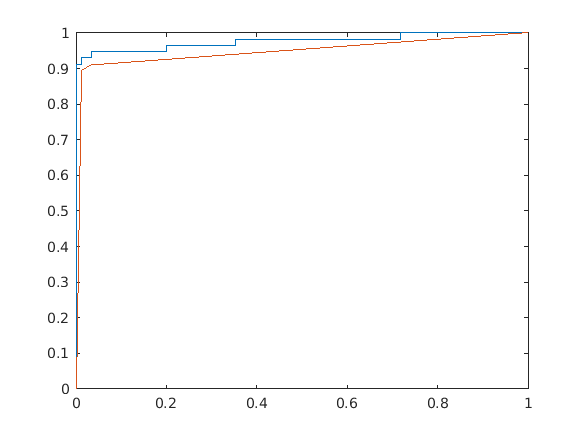

%generating ROC curve
[x,y] = perfcurve(test_labels, score_nb(:,2), 'Malignant');
[x1,y1] = perfcurve(test_labels, score_dt(:,2), 'Malignant');
%plotting the ROC curves on the same graph
plot(x,y)
hold on
plot(x1,y1)
hold off